clc;
clear;
close all;

load('modelo_lin.mat')

load("UncertainLinmodel.mat")





%USSlinmodel = createUSSmodel(linmodel,10)
%uvars = ufind(USSlinmodel)

Blingmod=linmodel.B(:,2);
Clingmod=linmodel.C(6,:);
Dlingmod=linmodel.D(6,2);

Glin=ss(linmodel.A,Blingmod,Clingmod,Dlingmod);
Glin.StateName=linmodel.StateName;
Glin.InputName = 'elevador';
Glin.OutputName = 'theta';

BUSSlingmod=USSlinmodel.B(:,2);
CUSSlingmod=USSlinmodel.C(6,:);
DUSSlingmod=USSlinmodel.D(6,2);

GUSSlin=ss(USSlinmodel.A,BUSSlingmod,CUSSlingmod,DUSSlingmod);
GUSSlin.StateName=USSlinmodel.StateName;
GUSSlin.InputName = 'elevador';
GUSSlin.OutputName = 'theta';

# Tarea1:

## Modelo Longitudinal:

%Carga del modelo
Alongmod = longmod.A;
Blongmod = longmod.B;
Clongmod = longmod.C;
Dlongmod = longmod.D;

%eliminacion de datos irrelevantes
Alongmod(abs(Alongmod)<1e-10)=0;
Blongmod(abs(Blongmod)<1e-10)=0;
Clongmod(abs(Clongmod)<1e-10)=0;
Dlongmod(abs(Dlongmod)<1e-10)=0;
longmodNames = longmod.StateName;
Blongmod=Blongmod(:,1);
Clongmod=Clongmod(4,:);
Dlongmod=Dlongmod(4,1);
G=ss(Alongmod,Blongmod,Clongmod,Dlongmod);
G.StateName=longmod.StateName

G =
 
  A = 
                   u           w
   u         -0.5961      0.8011
   w         -0.7454      -7.581
   q           1.042      -7.427
   theta           0           0
   Ze       -0.05377      0.9986
   omega       135.8       7.315
 
                   q       theta
   u          -0.871      -9.791
   w           15.72     -0.5272
   q          -15.85           0
   theta           1           0
   Ze              0         -17
   omega           0           0
 
                  Ze       omega
   u       5.053e-05     0.01263
   w      -0.0009384           0
   q               0    -0.01318
   theta           0           0
   Ze              0           0
   omega    -0.08268      -5.919
 
  B = 
              u1
   u      0.4681
   w      -2.711
   q      -134.1
   theta       0
   Ze          0
   omega       0
 
  C = 
           u      w      q
   y1      0      0      0
 
       theta     Ze  omega
   y1      1      0      0
 
  D = 
       u1
   y1   0
 
Continuous-t

G.InputName = 'elevador';
G.OutputName = 'theta';
s=tf('s');

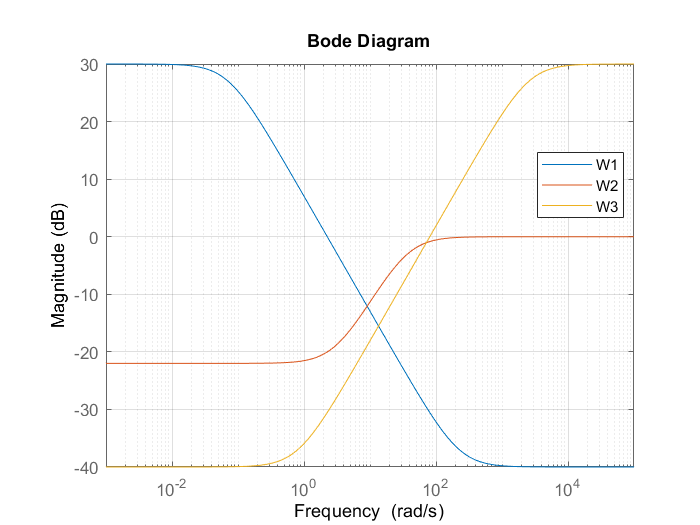

W1 = makeweight(db2mag(30),[8 db2mag(-11)],db2mag(-40)); %filtro pasa bajos
W2 = makeweight(db2mag(-22),[6 db2mag(-15)],db2mag(0)); 
W3 = makeweight(db2mag(-40),[8 db2mag(-20)],db2mag(30)); %filtro pasa altos

bodemag(W1,W2,W3)
legend("Location","best")
grid on

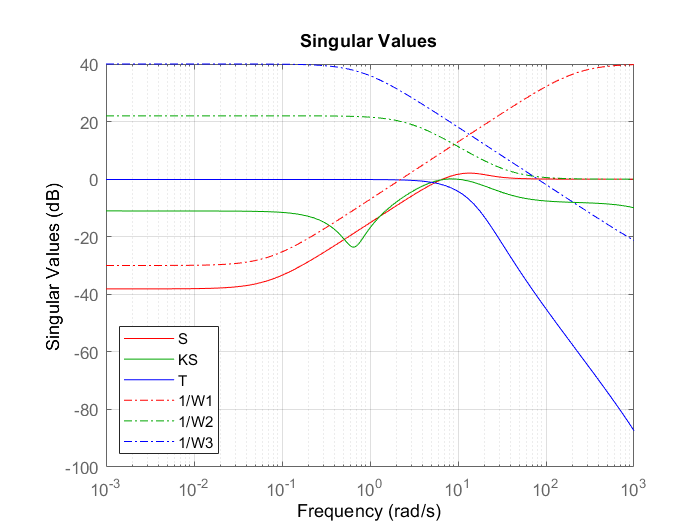


[K_Long,CL,gamma] = mixsyn(G,W1,W2,W3);
S = feedback(1,G*K_Long);
KS = K_Long*S;
T = 1-S;
sigma(S,'r',KS,'g',T,'b',1/W1,'r-.',ss(1/W2),'g-.',1/W3,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')
grid

ALL W

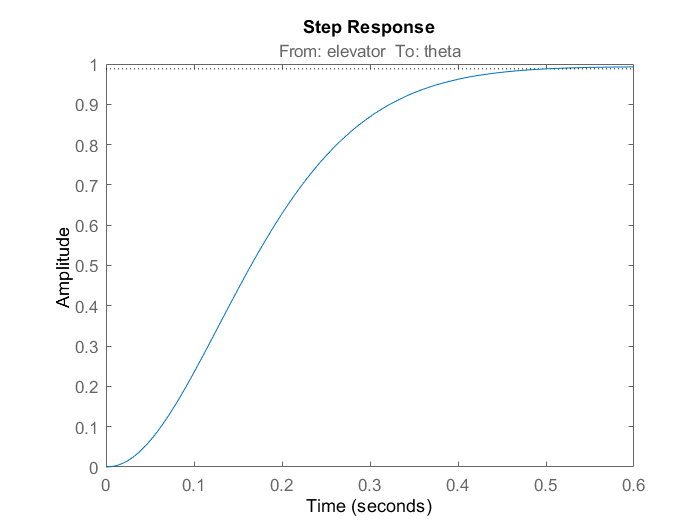

figure()
[K_Long,CL,gamma]=mixsyn(G,W1,W2,W3);
OL=series(K_Long,G);
GCL=feedback(OL,1);
GCL.InputName="elevator";
step(GCL)

bandwidth(GCL)

ans =    8.465227530852481


Ajustes

%axis([0 1 0 1.2])

format long
STINFOact=stepinfo(GCL)

STINFOact = struct with fields:
        RiseTime: 0.251932544506621
    SettlingTime: 0.413675221779779
     SettlingMin: 0.891189129102266
     SettlingMax: 0.992969426970768
       Overshoot: 0.522534585795986
      Undershoot: 0
            Peak: 0.992969426970768
        PeakTime: 0.631099212958143


STINFOprev=STINFOact;
%STINFOprev=STINFOact;
%STINFOprev=STINFOact;
%STINFOprev.Overshoot-STINFOact.Overshoot
%STINFOprev.Undershoot-STINFOact.Undershoot
%STINFOprev.RiseTime-STINFOact.RiseTime
DELTAPEAK=STINFOact.Peak-STINFOprev.Peak

DELTAPEAK =      0


DELTAPEAKTIME=STINFOact.PeakTime-STINFOprev.PeakTime

DELTAPEAKTIME =      0


%STINFOprev.SettlingMin-STINFOact.SettlingMin
%STINFOprev.SettlingMax-STINFOact.SettlingMax
DELTASETTIME=STINFOact.SettlingTime-STINFOprev.SettlingTime

DELTASETTIME =      0


STINFOprev=STINFOact;

Incertidumbre

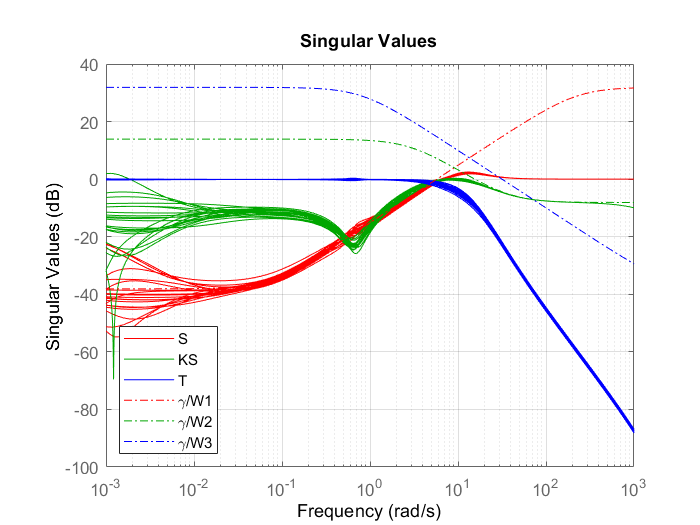

SUSS = feedback(1,GUSSlin*K_Long);
KSSUSS = K_Long*SUSS;
TSUSS = 1-SUSS;
sigma(SUSS,'r',KSSUSS,'g',TSUSS,'b',gamma/W1,'r-.',ss(gamma/W2),'g-.',gamma/W3,'b-.',{1e-3,1e3})
legend('S','KS','T','\gamma/W1','\gamma/W2','\gamma/W3','Location','SouthWest')
grid

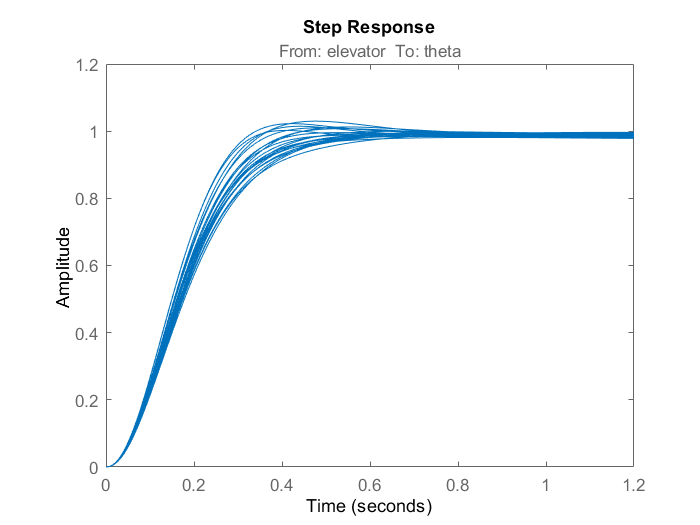


OLlinUSS=series(K_Long,GUSSlin);
GCLlinUSS=feedback(OLlinUSS,1);
GCLlinUSS.InputName="elevator";
step(GCLlinUSS)
axis([0 1.2 0 1.2])
hold off

bandwidth(GCLlinUSS)

ans =    8.376926652378467


stepinfo(GCLlinUSS)

ans = struct with fields:
        RiseTime: 0.253659333846804
    SettlingTime: 0.419187969013706
     SettlingMin: 0.896646703100390
     SettlingMax: 0.993812212076181
       Overshoot: 0.603696310313007
      Undershoot: 0
            Peak: 0.993812212076181
        PeakTime: 0.675591175546332


function [USSmodel] = createUSSmodel(linmodel,Delta)
% Create a new SS model with 5% uncertainty for each element of A,B,C and D

% Get the dimensions of A,B,C and D
[n,m] = size(linmodel.B);
[p,n] = size(linmodel.C);

% Create a ureal object with 5% uncertainty

% Iterate over each element of A,B,C and D and add uncertainty
for i=1:n
    for j=1:n
        if linmodel.A(i,j)~=0
            A(i,j) = ureal(['A' num2str(i) num2str(j)],linmodel.A(i,j),'Percentage',Delta);
            else
            A(i,j)=0;
        end
    end
    for j=1:m
        if linmodel.B(i,j)~=0
            B(i,j) = ureal(['B' num2str(i) num2str(j)],linmodel.B(i,j),'Percentage',Delta);
            else
            B(i,j)=0;
        end
    end
end

for i=1:p
    for j=1:n
        if linmodel.C(i,j)~=0
            C(i,j) = ureal(['C' num2str(i) num2str(j)],linmodel.C(i,j),'Percentage',Delta);
            else
            C(i,j)=0;
        end
    end
    for j=1:m
        if linmodel.D(i,j)~=0
            D(i,j) = ureal(['D' num2str(i) num2str(j)],linmodel.D(i,j),'Percentage',Delta);
        else
            D(i,j)=0;
        end
    end
end

% Create a USS model
USSmodel = uss(ss(A,B,C,D));

end